# Matrix Operations

 This live script is intended to be used with the code hidden. Select the `VIEW` tab and switch to `Hide Code`.

## Matrices

Run this section to redefine the numeric version of the matrices $A$, $B$, the scalar $c$, and the vector $v$.

 
close all
clear all
[Ai,Bi,ci,vi] = defineMatrices();

#### 1. Definition

A matrix is a rectangular set of elements. The $m \times n$ matrix shown here has $m$ rows and $n$ columns.


$$A = \left(\begin{array}{ccc}
a_{11}  &  a_{12} & \ldots  & a_{1n} \\
a_{21} & a_{22}   & \ldots  & a_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
a_{m1}  & a_{m2} & \ldots  & a_{mn} 
\end{array}\right)$$


Each element is denoted $a_{i,j}$, where $i$ refers to the row and $j$ to the column.

  **Try**. Adjust the number of rows, $n$, and the number of columns, $n$, to view matrices of different sizes.

m = 4;
n = 3; 
numeric = true;
 
if(~exist("Ai","var"))
    [Ai,Bi,ci,vi] = defineMatrices();
end
if(numeric) 
    A = sym(Ai(1:m,1:n))
else
    A = sym('a',[m,n])
end

$$A = \left(\begin{array}{ccc} 4 & 7 & 9\\ 6 & 6 & 3\\ 9 & 5 & 3\\ 9 & 3 & 2 \end{array}\right)$$

#### 2. Addition

To add two $n \times m$ matrices, add their corresponding elements.


$$A + B = \left(\begin{array}{ccc}
a_{11}  &  a_{12} & \ldots  & a_{1n} \\
a_{21} & a_{22}   & \ldots  & a_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
a_{m1}  & a_{m2} & \ldots  & a_{mn} 
\end{array}\right) 
+ 
\left(\begin{array}{ccc}
b_{11}  &  b_{12} & \ldots  & b_{1n} \\
b_{21} & b_{22}   & \ldots  & b_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
b_{m1}  & b_{m2} & \ldots  & b_{mn} 
\end{array}\right)$$


           
$$= \left(\begin{array}{ccc}
a_{11} + b_{11}  &  a_{12} + b_{12} & \ldots  & a_{1n} +b_{1n}  \\
a_{21} + b_{21} & a_{22} + b_{22} & \ldots  & a_{2n} + b_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
a_{m1}  + b_{m1} & a_{m2} + b_{m2} & \ldots  & a_{mn}  + b_{mn} 
\end{array}\right)$$


 **Example**. Subtract matrices A and B. You can adjust their sizes. 

m = 3;
n = 2; 
 
if(~exist("Ai","var"))
    [Ai,Bi,ci,vi] = defineMatrices();
end
A = sym(Ai(1:m,1:n))

$$A = \left(\begin{array}{cc} 4 & 7\\ 6 & 6\\ 9 & 5 \end{array}\right)$$

B = sym(Bi(1:m,1:n))

$$B = \left(\begin{array}{cc} 1 & 7\\ 6 & 9\\ 8 & 8 \end{array}\right)$$

showSolution = true;
if(showSolution)
    AminusB = A-B
end

$$AminusB = \left(\begin{array}{cc} 3 & 0\\ 0 & -3\\ 1 & -3 \end{array}\right)$$

To add two matrices, they must be the same size.

#### 3. Multiplication by a scalar

When multiplying a matrix $A$ by a scalar $c$ multiply each element by the scalar.


$$cA = \left(\begin{array}{ccc}
ca_{11}  &  ca_{12} & \ldots  & ca_{1n} \\
ca_{21} & ca_{22}   & \ldots  & ca_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
ca_{m1}  & ca_{m2} & \ldots  & ca_{mn} 
\end{array}\right)$$


Each element is denoted $a_{i,j}$, where $i$ refers to the row and $j$ to the column.

 **Example**. Multiply the matrix $A$ by the scalar $c$. You can adjust the size of $A$.

m = 4;
n = 2; 
 
if(~exist("Ai","var"))
    [Ai,Bi,ci,vi] = defineMatrices();
end
A = sym(Ai(1:m,1:n))

$$A = \left(\begin{array}{cc} 4 & 7\\ 6 & 6\\ 9 & 5\\ 9 & 3 \end{array}\right)$$

c = sym(ci)

$$c = 2$$

showSolution2 = true;
if(showSolution2)
    cA = ci*A
end

$$cA = \left(\begin{array}{cc} 8 & 14\\ 12 & 12\\ 18 & 10\\ 18 & 6 \end{array}\right)$$

#### 3. Multiplication by a column vector

The product of a matrix $A$ and a column vector $v$ yields a column vector. The entries of $Av$ are the dot product of the rows of $A$ with the vector $v$. 


$$Av = \left(\begin{array}{ccc}
a_{11}  &  a_{12} & \ldots  & a_{1n} \\
a_{21} & a_{22}   & \ldots  & a_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
a_{m1}  & a_{m2} & \ldots  & a_{mn} 
\end{array}\right)
\left(\begin{array}{ccc}
v_{1} \\
v_{2} \\
\vdots \\
v_{n} 
\end{array}\right)$$


      
$$= \left(\begin{array}{ccc}
a_{11} v_1  +  a_{12} v_2  + \ldots  + a_{1n}v_n \\
a_{21} v_1  +  a_{22} v_2  + \ldots  + a_{2n}v_n\\
\vdots \\
a_{m1} v_1  +  a_{m2} v_2  + \ldots  + a_{mn}v_n\\
\end{array}\right)$$


In order to take the dot product of the rows of $A$ and the vector $v$, the number of columns in $A$ must match the number of elements in $v$. This implies $v$ must have $n$ entries.

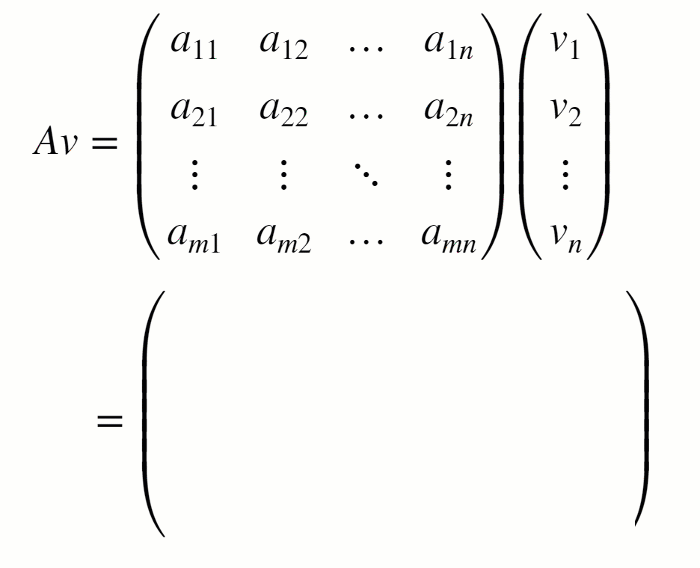

*Animation of Matrix-Vector multiplication. Each entry in the result is created by taking the dot product of the matrix row and the vector.*

 **Example**. Multiply the matrix $A$ by the vector $v$. You can adjust the sizes.

m = 2;
n = 4; 
 
if(~exist("Ai","var"))
    [Ai,Bi,ci,vi] = defineMatrices();
end
A = sym(Ai(1:m,1:n))

$$A = \left(\begin{array}{cccc} 4 & 7 & 9 & 8\\ 6 & 6 & 3 & 4 \end{array}\right)$$

v = sym(vi(1:n))

$$v = \left(\begin{array}{c} 9\\ 9\\ 2\\ 5 \end{array}\right)$$

if(~exist("Ai","var"))
    [Ai,Bi,ci,vi] = defineMatrices();
end
showSolution3 = true;
if(showSolution3)
    Av = A*v
end

$$Av = \left(\begin{array}{c} 157\\ 134 \end{array}\right)$$

#### 3. Multiplication by another matrix

The product of a $m \times n$ matrix $A$ and a $n \times p$ matrix $B$ is a $m \times p$ matrix $C$, defined below.  Note that the "inner" dimensions of $A$ and $B$ must match for their product to be defined.


$$AB = \left(\begin{array}{ccc}
a_{11}  &  a_{12} & \ldots  & a_{1n} \\
a_{21} & a_{22}   & \ldots  & a_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
a_{m1}  & a_{m2} & \ldots  & a_{mn} 
\end{array}\right)

\left(\begin{array}{ccc}
b_{11}  & b_{12} & \ldots  & b_{1p} \\
b_{21} & b_{22}   & \ldots  & b_{2p} \\
\vdots &  \vdots   & \ddots  & \vdots \\
b_{n1}  & b_{n2} & \ldots  & b_{np} 
\end{array}\right)$$


      
$$=
\left(\begin{array}{ccc}
c_{11}  & c_{12} & \ldots  & c_{1p} \\
c_{21} & c_{22}   & \ldots  & c_{2p} \\
\vdots &  \vdots   & \ddots  & \vdots \\
c_{m1}  & c_{m2} & \ldots  & c_{mp} 
\end{array}\right)$$


where


$$c_{ij} = \sum_{k} a_{ik}b_{kj}$$


If the inner dimensions of the matrices do not match, the rows of $A$ will not have the same length as the columns of $B$, and this sum will not be defined.

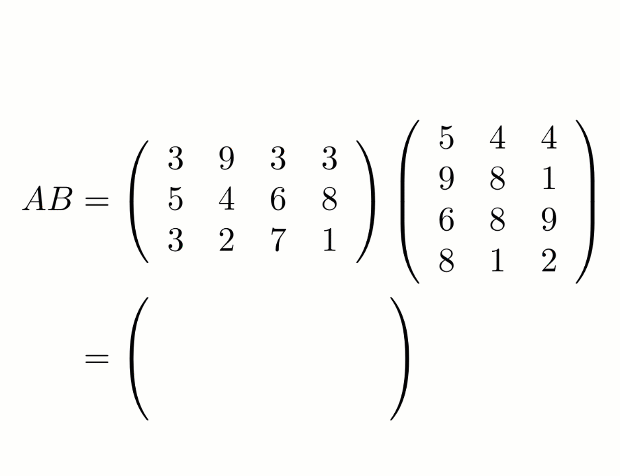

*Example of matrix multiplication. Each element in the product is created by taking the dot product of a row of A with a column of B.*

 **Example**. Multiply the matrices $A$ and $B$. You can adjust the sizes.

m = 3;
n = 3; 
p = 2;
 
if(~exist("Ai","var"))
    [Ai,Bi,ci,vi] = defineMatrices();
end
A = sym(Ai(1:m,1:n))

$$A = \left(\begin{array}{ccc} 4 & 7 & 9\\ 6 & 6 & 3\\ 9 & 5 & 3 \end{array}\right)$$

B = sym(Bi(1:n,1:p))

$$B = \left(\begin{array}{cc} 1 & 7\\ 6 & 9\\ 8 & 8 \end{array}\right)$$

showSolution3 = true;
if(showSolution3)
    AB = A*B
end

$$AB = \left(\begin{array}{cc} 118 & 163\\ 66 & 120\\ 63 & 132 \end{array}\right)$$

#### 4. Determinant

The determinant is a scalar value that characterizes important properties of a square ($n \times n$) matrix. The determinant is not defined for non-square matrices. The determinant of a matrix is denoted using vertical lines $| \cdot |$. 

**Determinant of a 2x2 matrix**

The determinant of a 2x2 matrix is

$\det(A) = \left| \matrix{a & b \cr c & d } \right| = ad - bc$.

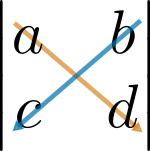

*You can think of the determinant of a 2x2 matrix as subtracting the product of the off-diagonal elements from the product of the diagonal elements.*

The determinants of larger matrices can be computed algorithmically using determinants of submatrices. This process is known as the Laplace expansion. 

**Determinant of a 3x3 matrix**

You can use the Laplace expansion to compute the determinant of a 3x3 matrix using 2x2 submatrices.


$$\det(A) = \left| \matrix{a & b & c \cr d & e & f \cr g & h & i } \right| = a \left| \matrix{ e & f \cr h & i } \right| - b \left| \matrix{ d & f \cr g & i } \right|  +c \left| \matrix{ d & e \cr g & h } \right|$$


You can compute the determinants of the 2x2 matrices using the formula defined above.

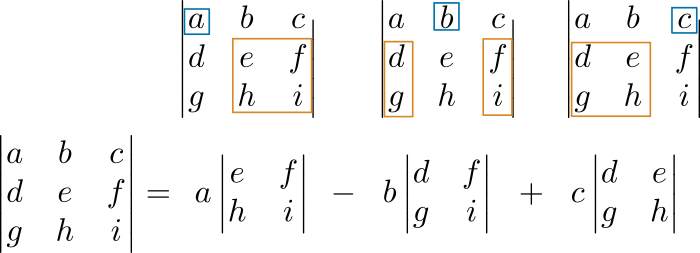

*Schematic of the Laplace expansion for a 3x3 matrix. Visualize selecting one element from the first row and then selecting the submatrix from the other rows and columns. Also watch out for the sign changes.*

You can similarly expand larger matrices to break them down in terms of smaller matrices. However, for such cases, numerical software is typically used.

 **Example**. Compute the determinant of $A$. You can adjust the size.

n = 3; 
 
if(~exist("Ai","var"))
    [Ai,Bi,ci,vi] = defineMatrices();
end
A = sym(Ai(1:n,1:n))

$$A = \left(\begin{array}{ccc} 4 & 7 & 9\\ 6 & 6 & 3\\ 9 & 5 & 3 \end{array}\right)$$

showSolutiond = true;
if(showSolutiond)
    detA = det(A)
end

$$detA = -141$$

function [Ai,Bi,ci,vi] = defineMatrices()
    Ai = randi(9,10,10);
    Bi = randi(9,10,10);
    ci = randi(8)+1;
    vi = randi(9,10,1);
end